GMOS Implementation  Demonstation

 clear
  clc

set(0,'DefaultFigureWindowStyle','normal');

set(groot,'DefaultTextInterpreter','latex');
set(groot,'DefaultAxesTickLabelInterpreter','latex');
set(groot,'DefaultLegendInterpreter','latex');
set(groot,'DefaultAxesFontSize',20);
set(groot,'DefaultTextFontSize',22);

% -------------------------
% Constants
% -------------------------
mu_EM_JPL = 1.215058560962404e-2;

% -------------------------
% Load one periodic orbit
% -------------------------
orbit_index= 400

orbit_index = 400

po = pick_po_from_JPL('L1_Lyapunov_orbits_JPL_IC_Earth_Moon.csv', orbit_index);



% orbit_index= 896
% po = pick_po_from_JPL('L1_northern_halo_orbits_JPL_IC_Earth_Moon.csv', orbit_index);


xPO0 = po.x0;          % 6x1
TPO  = po.T;           % scalar

% 
% x0_Kaushik=[0.8533092408794802, -0.10002264189296393,  0, -0.06943835422503508,  0.008020539706976249,  0.0]
% TP0_Kaushik= 2.8635612043970644
% xPO0 = po.x0;          % 6x1
% TPO  = po.T;           % scalar
% 
% 
% 
% 
% xPO0 = x0_Kaushik;          % 6x1
% TPO  = TP0_Kaushik;  
JC_Lyap=Jacobi_Constant(xPO0, mu_EM_JPL)

JC_Lyap = 2.9881


fprintf('Using orbit index  %.15f\n', orbit_index');

Using orbit index  400.000000000000000


fprintf('TPO = %.15f\n', TPO);

TPO = 4.593485557331357


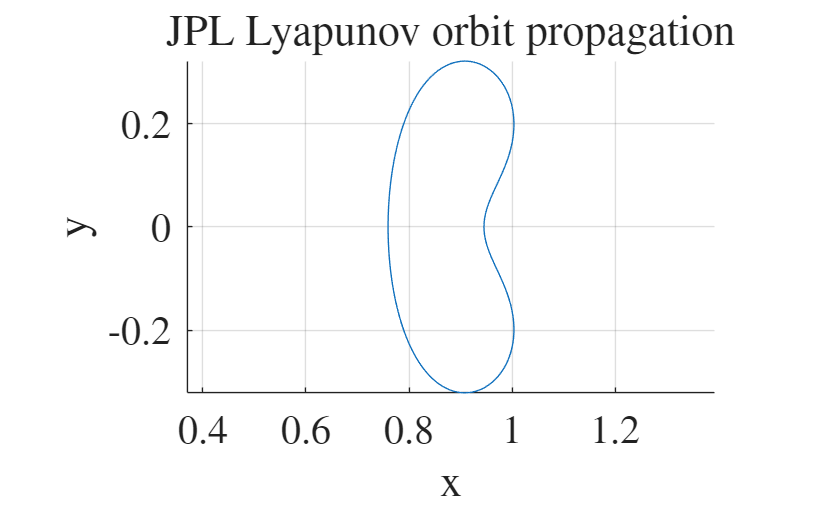


% -------------------------
% Quick trajectory plot (optional)
% -------------------------
[t_eval, Y_eval] = IntegrateCR3BP_ODE89(xPO0, [0, TPO], mu_EM_JPL, 1e3);

figure;
hold on; grid on; axis equal;
plot3(Y_eval(:,1), Y_eval(:,2), Y_eval(:,3));
xlabel('x'); ylabel('y'); zlabel('z');
title('JPL Lyapunov orbit propagation');


% -------------------------
% Closure test (must be small)
% -------------------------
ode_opts = odeset('RelTol', 1e-12, 'AbsTol', 1e-12);

sol = ode89(@(t,Y) CR3BP_mu(t, Y, mu_EM_JPL), [0, TPO], xPO0, ode_opts);
x_end = sol.y(:, end);

fprintf('PO closure error ||Phi^T(xPO0)-xPO0|| = %.3e\n', norm(x_end - xPO0));

PO closure error ||Phi^T(xPO0)-xPO0|| = 2.758e-11


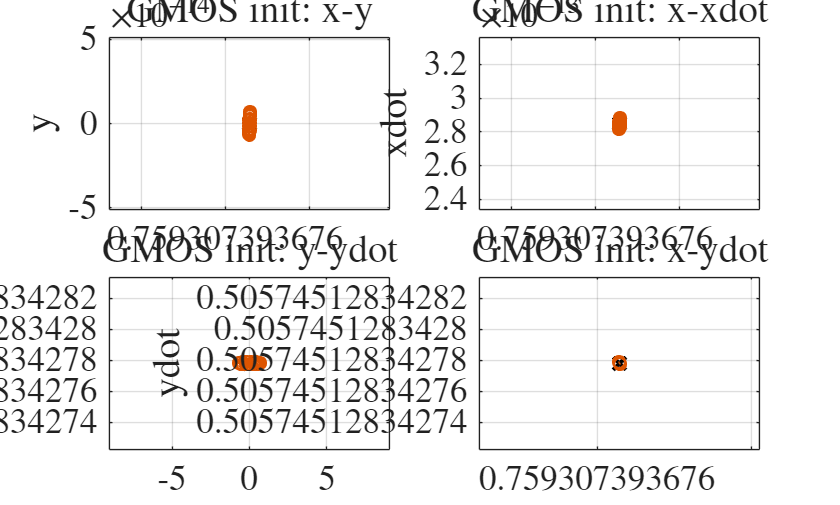

Mode: vertical
Eigenvector projections: planar 8.128e-14, vertical 1.000e+00
Init amplitude [x y z xd yd zd] = [8.88e-16 1.42e-14 2.40e-02 7.61e-15 2.00e-15 1.98e-01]
Max init amplitude: component 6, amp = 1.984e-01
Linearization test at j=1:
  ||dx0||      = 9.928e-02
  ||dx1||      = 1.266e+00
  ||dx1_lin||  = 5.345e-02
  ||dx1-dx1lin|| = 1.267e+00
Inf residual: +rho 8.942e-01, -rho 8.943e-01, using sign 1
||Finv||2   = 5.642e+00
||Finv||inf = 8.942e-01


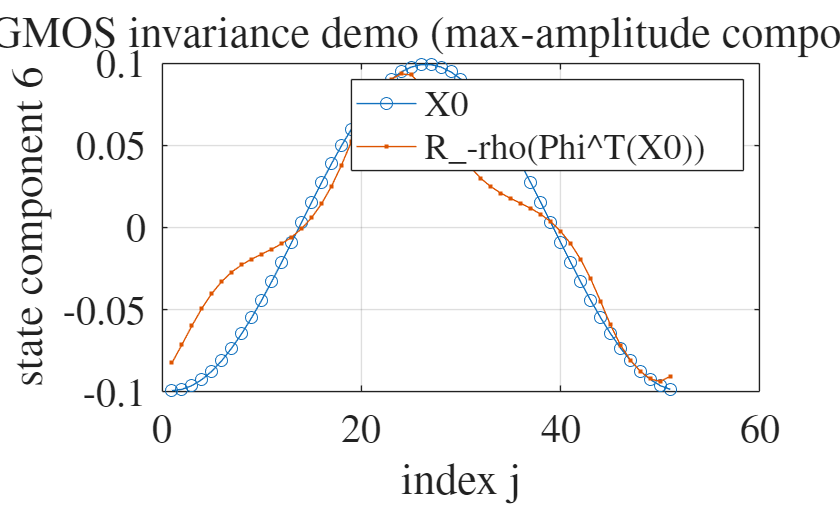

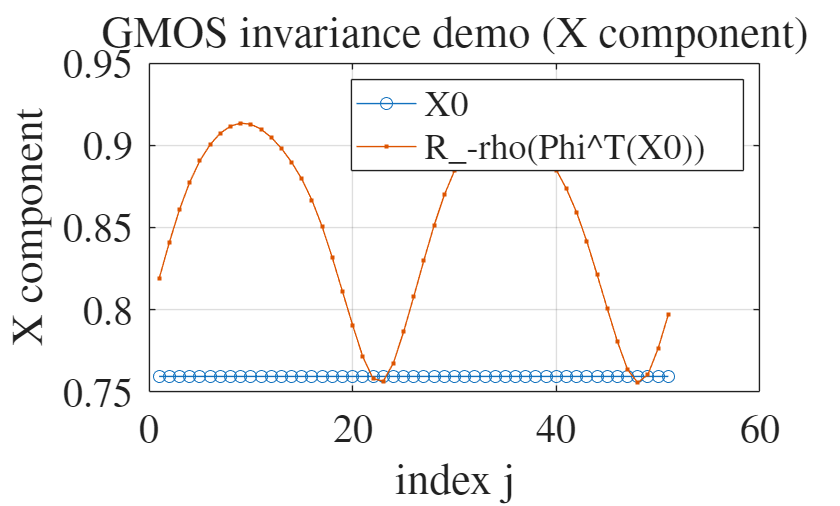


% -------------------------
% GMOS invariance-only demo
% -------------------------
N = 51;
K = 1e-1;
doPlot = true;

demo = gmos_demo_invariance_only(mu_EM_JPL, xPO0, TPO, N, K, doPlot, 'vertical');


init = demo.init;    % make sure init is defined now

% -------------------------
% Shift self-test (must use the curve, not a single state)
% -------------------------
X0 = init.X0;  % 6xN

X0p = gmos_shift_curve_fft(X0,  init.rho0);
X0m = gmos_shift_curve_fft(X0, -init.rho0);

fprintf('Shift self-test:\n');

Shift self-test:


fprintf('  ||X0p-X0||inf = %.3e\n', norm(X0p(:) - X0(:), inf));

  ||X0p-X0||inf = 9.640e-02


fprintf('  ||X0m-X0||inf = %.3e\n', norm(X0m(:) - X0(:), inf));

  ||X0m-X0||inf = 9.640e-02


fprintf('  ||X0p-X0m||inf = %.3e\n', norm(X0p(:) - X0m(:), inf));

  ||X0p-X0m||inf = 1.685e-01



% -------------------------
% Perturbed vs unperturbed closeness test
% -------------------------
sol0 = ode89(@(t,Y) CR3BP_mu(t, Y, mu_EM_JPL), [0, TPO], xPO0, ode_opts);
x_end0 = sol0.y(:, end);

x0j = init.X0(:, 1);
solp = ode89(@(t,Y) CR3BP_mu(t, Y, mu_EM_JPL), [0, TPO], x0j, ode_opts);
x_endp = solp.y(:, end);

fprintf('Closeness test:\n');

Closeness test:


fprintf('  ||x0j - xPO0||       = %.3e\n', norm(x0j - xPO0));

  ||x0j - xPO0||       = 9.928e-02


fprintf('  ||x_endp - x_end0||  = %.3e\n', norm(x_endp - x_end0));

  ||x_endp - x_end0||  = 1.266e+00


fprintf('  ||x_end0 - xPO0||    = %.3e (closure)\n', norm(x_end0 - xPO0));

  ||x_end0 - xPO0||    = 2.758e-11 (closure)


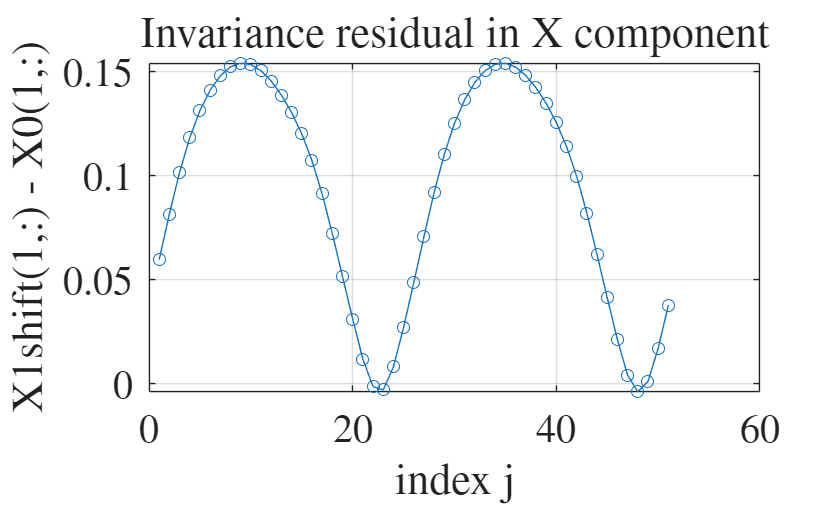

figure;
plot(1:N, (demo.X1shift(1,:) - demo.init.X0(1,:)), 'o-');
grid on;
xlabel('index j');
ylabel('X1shift(1,:) - X0(1,:)');
title('Invariance residual in X component');

tic

% Choose N smaller for the first Newton test
N = 51;

% Build init (use your existing pipeline)
demo = gmos_demo_invariance_only(mu_EM_JPL, xPO0, TPO, N, 1e-6, false, 'vertical');

Mode: vertical
Eigenvector projections: planar 8.128e-14, vertical 1.000e+00
Init amplitude [x y z xd yd zd] = [0.00e+00 1.42e-19 2.40e-07 7.61e-20 0.00e+00 1.98e-06]
Max init amplitude: component 6, amp = 1.984e-06
Linearization test at j=1:
  ||dx0||      = 9.928e-07
  ||dx1||      = 5.345e-07
  ||dx1_lin||  = 5.345e-07
  ||dx1-dx1lin|| = 9.313e-11
Inf residual: +rho 7.473e-11, -rho 1.686e-06, using sign 1
||Finv||2   = 3.874e-10
||Finv||inf = 7.473e-11


init = demo.init;

% Reference for phase conditions (first solve)
Xref   = init.X0;
Tref   = init.T0;
rhoref = init.rho0;

% Initial unknown vector
z0 = gmos_pack_z(init.X0, init.T0, init.rho0);

% Fix T exactly to the periodic orbit period
Ttarget = TPO;

optsN = struct();
optsN.maxIter = 12;
optsN.tolInf  = 1e-10;
optsN.verbose = true;

[z_sol, info] = gmos_newton_fixT_analytic(z0, N, mu_EM_JPL, Xref, Tref, rhoref, Ttarget, ode_opts, optsN);

Newton iter  1: ||F||inf = 7.307e-11, ||F||2 = 3.778e-10



[X0_sol, T_sol, rho_sol] = gmos_unpack_z(z_sol, N);
fprintf('Solved: T = %.15f, rho = %.15f\n', T_sol, rho_sol);

Solved: T = 4.593485557331357, rho = 1.013999616412891



toc

Elapsed time is 0.616977 seconds.


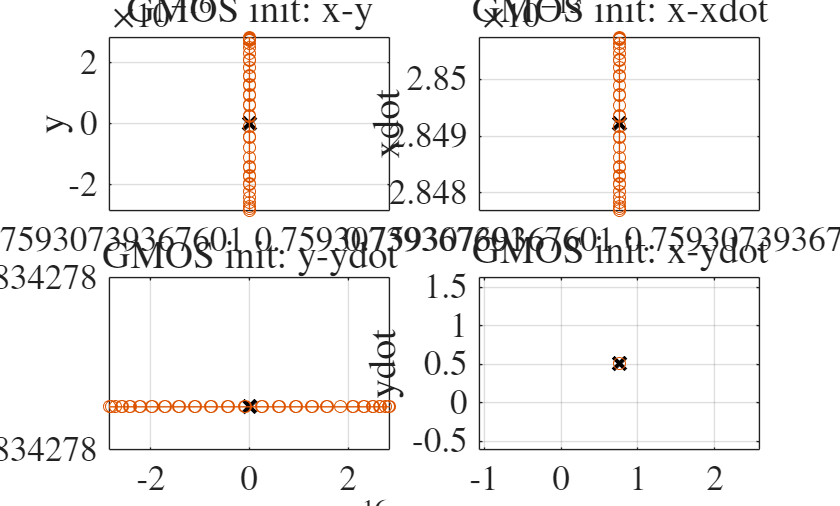

Mode: vertical
Eigenvector projections: planar 8.128e-14, vertical 1.000e+00
Init amplitude [x y z xd yd zd] = [0.00e+00 5.68e-16 9.60e-04 3.04e-16 0.00e+00 7.93e-03]
Max init amplitude: component 6, amp = 7.935e-03
Linearization test at j=1:
  ||dx0||      = 3.971e-03
  ||dx1||      = 2.877e-03
  ||dx1_lin||  = 2.138e-03
  ||dx1-dx1lin|| = 1.929e-03
Inf residual: +rho 1.561e-03, -rho 6.742e-03, using sign 1
||Finv||2   = 8.446e-03
||Finv||inf = 1.561e-03


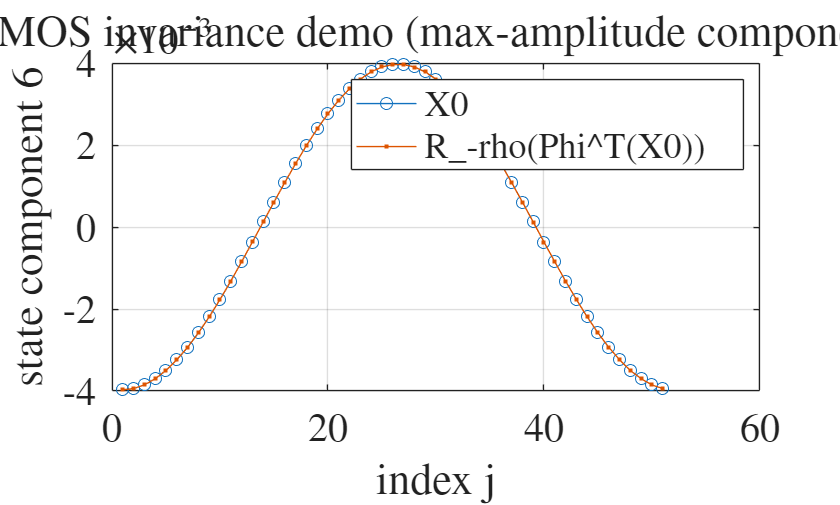

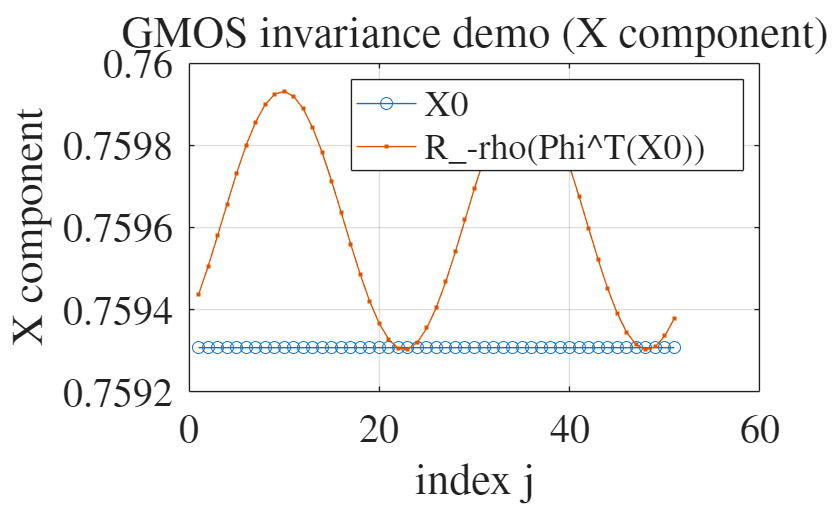

% Settings

ode_opts = odeset('RelTol',1e-12,'AbsTol',1e-12);
Ttarget = TPO;

% Build two inits with different K
demo0 = gmos_demo_invariance_only(mu_EM_JPL, xPO0, TPO, N, 4e-3, true, 'vertical');

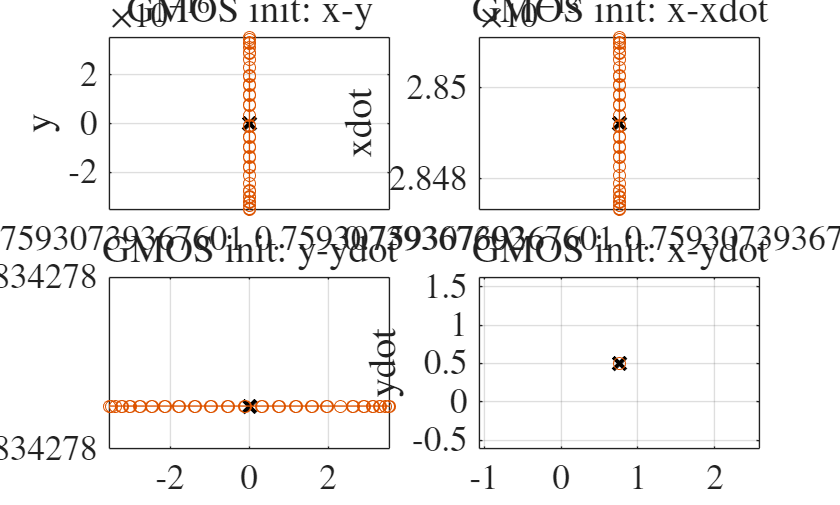

Mode: vertical
Eigenvector projections: planar 8.128e-14, vertical 1.000e+00
Init amplitude [x y z xd yd zd] = [0.00e+00 7.10e-16 1.20e-03 3.80e-16 0.00e+00 9.92e-03]
Max init amplitude: component 6, amp = 9.918e-03
Linearization test at j=1:
  ||dx0||      = 4.964e-03
  ||dx1||      = 4.022e-03
  ||dx1_lin||  = 2.672e-03
  ||dx1-dx1lin|| = 3.011e-03
Inf residual: +rho 2.440e-03, -rho 8.428e-03, using sign 1
||Finv||2   = 1.319e-02
||Finv||inf = 2.440e-03


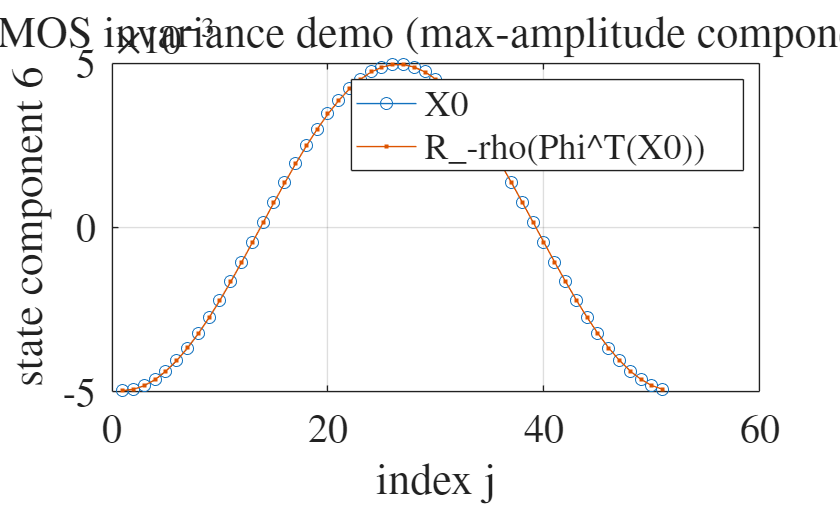

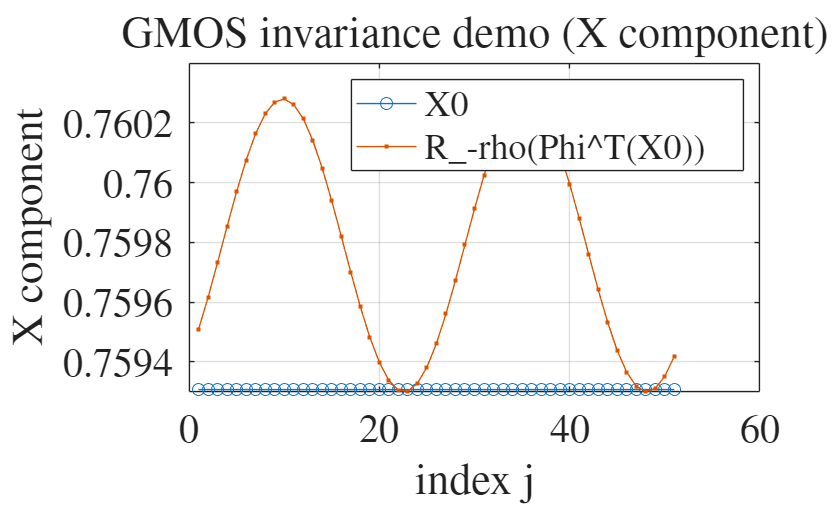

demo1 = gmos_demo_invariance_only(mu_EM_JPL, xPO0, TPO, N, 5e-3, true, 'vertical');


init0 = demo0.init;
init1 = demo1.init;

% Reference for phase conditions (paper): use the first solution as reference
Xref   = init0.X0;
Tref   = init0.T0;
rhoref = init0.rho0;

% Solve both with fixed T analytic Newton (no pseudo arclength yet)
z0 = gmos_pack_z(init0.X0, init0.T0, init0.rho0);
z1 = gmos_pack_z(init1.X0, init1.T0, init1.rho0);

optsN = struct('maxIter', 12, 'tolInf', 1e-10, 'verbose', true);

[z0_sol, ~] = gmos_newton_fixT_analytic(z0, N, mu_EM_JPL, Xref, Tref, rhoref, Ttarget, ode_opts, optsN);

Newton iter  1: ||F||inf = 1.561e-03, ||F||2 = 8.446e-03
Newton iter  2: ||F||inf = 1.648e-05, ||F||2 = 8.410e-05
Newton iter  3: ||F||inf = 3.726e-05, ||F||2 = 2.020e-04
Newton iter  4: ||F||inf = 4.924e-09, ||F||2 = 1.959e-08
Newton iter  5: ||F||inf = 2.088e-13, ||F||2 = 7.914e-13


[z1_sol, ~] = gmos_newton_fixT_analytic(z1, N, mu_EM_JPL, Xref, Tref, rhoref, Ttarget, ode_opts, optsN);

Newton iter  1: ||F||inf = 2.440e-03, ||F||2 = 1.319e-02
Newton iter  2: ||F||inf = 2.556e-04, ||F||2 = 1.353e-03
Newton iter  3: ||F||inf = 8.552e-04, ||F||2 = 4.628e-03
Newton iter  4: ||F||inf = 2.340e-06, ||F||2 = 1.082e-05
Newton iter  5: ||F||inf = 1.414e-08, ||F||2 = 5.730e-08
Newton iter  6: ||F||inf = 5.625e-13, ||F||2 = 2.335e-12



% Continue the family
ds = 0.9e-2;      % step in z-space (tune)

%ds = 1e-4;      % step in z-space (tune)
nSteps =1

nSteps = 1


resultsFile = 'fam_fixT_LyapL1.mat';


    tic
    fam = gmos_continue_fixT_family( ...
        z0_sol, z1_sol, nSteps, ds, N, mu_EM_JPL, Ttarget, ode_opts, optsN);

Newton iter  1: ||F||inf = 6.673e-04, ||F||2 = 3.614e-03
Newton iter  2: ||F||inf = 1.649e-06, ||F||2 = 6.250e-06
Newton iter  3: ||F||inf = 4.904e-09, ||F||2 = 2.299e-08
Newton iter  4: ||F||inf = 2.246e-13, ||F||2 = 7.811e-13
Continuation step 1/1: T = 4.593485557331357, rho = 1.013813219672334, final ||F||inf = 2.246e-13


   toc

Elapsed time is 1.937295 seconds.


    %save(resultsFile, ...
      %  'fam', 'z0_sol', 'z1_sol', 'nSteps', 'ds', 'N', 'mu_EM_JPL', ...
     %   'Ttarget', 'ode_opts', 'optsN', '-v7.3');

    fprintf('Saved family and settings to %s\n', resultsFile);

Saved family and settings to fam_fixT_LyapL1.mat


   load(resultsFile, ...
       'fam', 'z0_sol', 'z1_sol', 'nSteps', 'ds', 'N', 'mu_EM_JPL', ...
       'Ttarget', 'ode_opts', 'optsN');

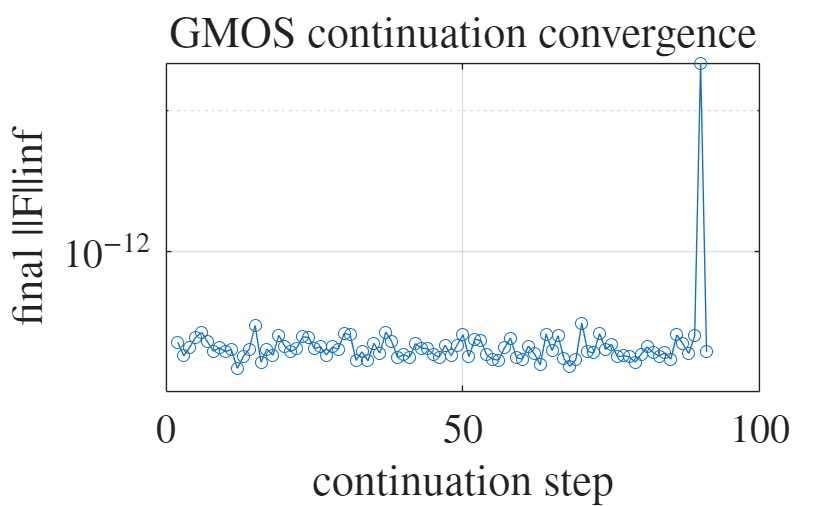

k = 0:(numel(fam.rho)-1);   % step index (adjust if you start at 1/2 seeds)

figure;
semilogy(k, fam.normInf, 'o-');
grid on;
xlabel('continuation step');
ylabel('final ||F||inf');
title('GMOS continuation convergence');

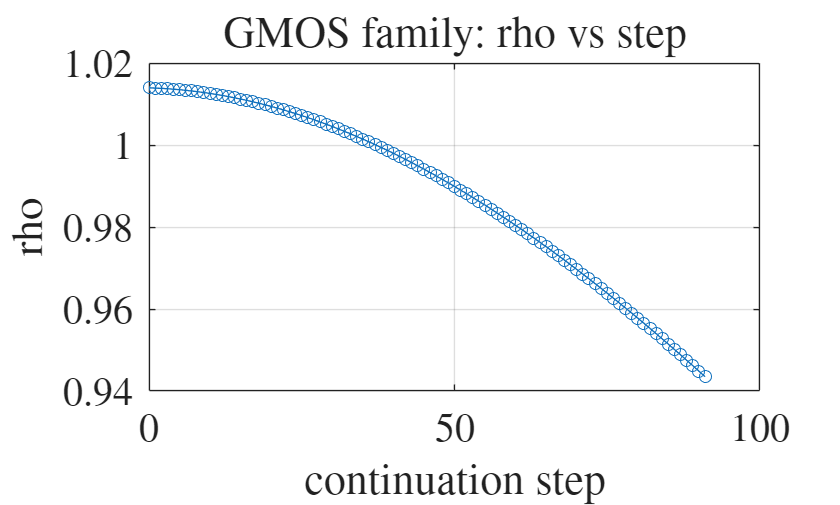



k = 0:(numel(fam.rho)-1);

figure;
plot(k, fam.rho, 'o-');
grid on;
xlabel('continuation step');
ylabel('rho');
title('GMOS family: rho vs step');

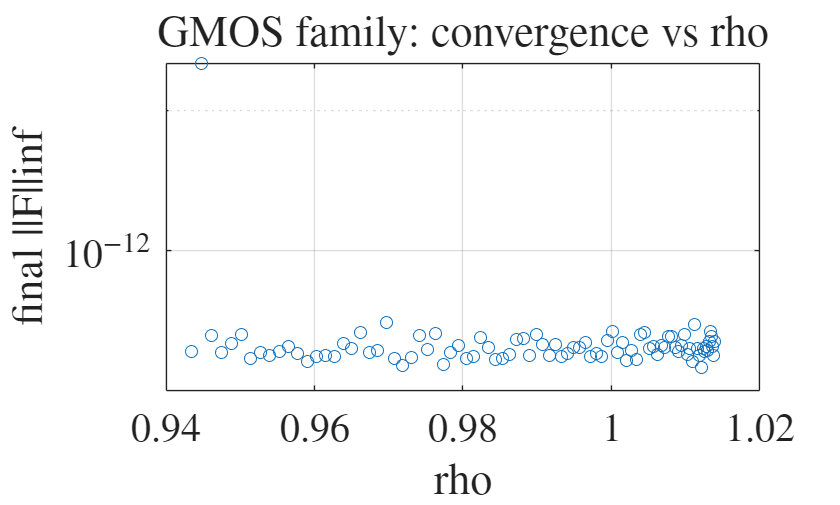




figure;
semilogy(fam.rho, fam.normInf, 'o');
grid on;
xlabel('rho');
ylabel('final ||F||inf');
title('GMOS family: convergence vs rho');

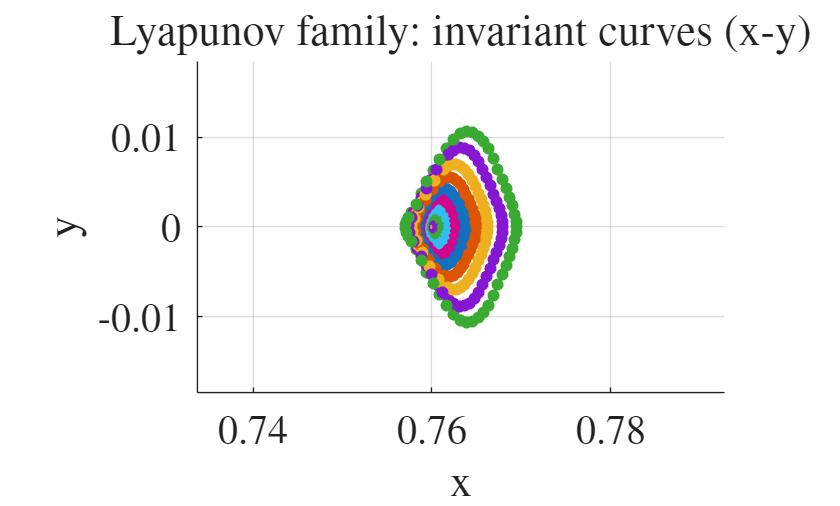

  % must match your continuation N

idxList = unique(round(linspace(1, numel(fam.z), min(12, numel(fam.z)))));

figure; hold on; grid on; axis equal;
for ii = idxList(:).'
    z = fam.z{ii};
    [X0, T, rho] = gmos_unpack_z(z, N);

    scatter3(X0(1,:), X0(2,:),X0(3,:), 'filled');   % x-y projection of the curve
end
xlabel('x'); ylabel('y');
title('Lyapunov family: invariant curves (x-y)');

%legend(arrayfun(@(ii) sprintf('step %d', ii-1), idxList, 'UniformOutput', false));

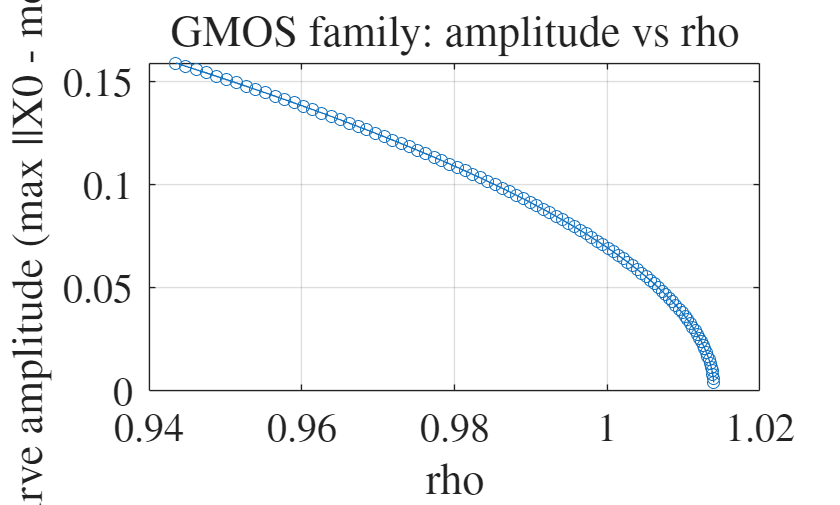


nSol = numel(fam.z);

amp = zeros(nSol,1);
for i = 1:nSol
    [X0, ~, ~] = gmos_unpack_z(fam.z{i}, N);
    Xm = mean(X0, 2);
    amp(i) = max(vecnorm(X0 - Xm, 2, 1));  % max column 2-norm deviation
end

figure;
plot(fam.rho, amp, 'o-');
grid on;
xlabel('rho');
ylabel('curve amplitude (max ||X0 - mean||)');
title('GMOS family: amplitude vs rho');


k = numel(fam.z);           % last family solution, for example
z = fam.z{40};

% Propagate every ith sample on the curve
jList = 1:3:N;

nPeriods = 4;              % total time = 10*T
nSavePerPeriod = 300;       % smooth curves
ode_opts = odeset('RelTol',1e-13,'AbsTol',1e-13);

traj = gmos_propagate_qpos_orbits(z, N, mu_EM_JPL, jList, nPeriods, nSavePerPeriod, ode_opts); 


% Color by index (different colors), opaque
%gmos_plot_qpos_orbits_3d(traj, struct('mode','index','alpha',1,'lineWidth',1.0));

% % Gray with transparency
% gmos_plot_qpos_orbits_3d(traj, struct('mode','gray','gray',0.2,'alpha',0.15,'lineWidth',1.0));
% 
 % Single custom RGB color with transparency (e.g., teal)
 gmos_plot_qpos_orbits_3d(traj, struct('mode','rgb','rgb',[0.7 0.0 0.1],'alpha',0.1,'lineWidth',1.5));
 plot_Moon_nd(1e3,1,1)

ans =   Surface with properties:

       EdgeColor: 'none'
       LineStyle: '-'
       FaceColor: 'texturemap'
    FaceLighting: 'flat'
       FaceAlpha: 1
           XData: [1001×1001 double]
           YData: [1001×1001 double]
           ZData: [1001×1001 double]
           CData: [1024×2048×3 uint8]

  Show all properties

  Show all accessible properties of Surface


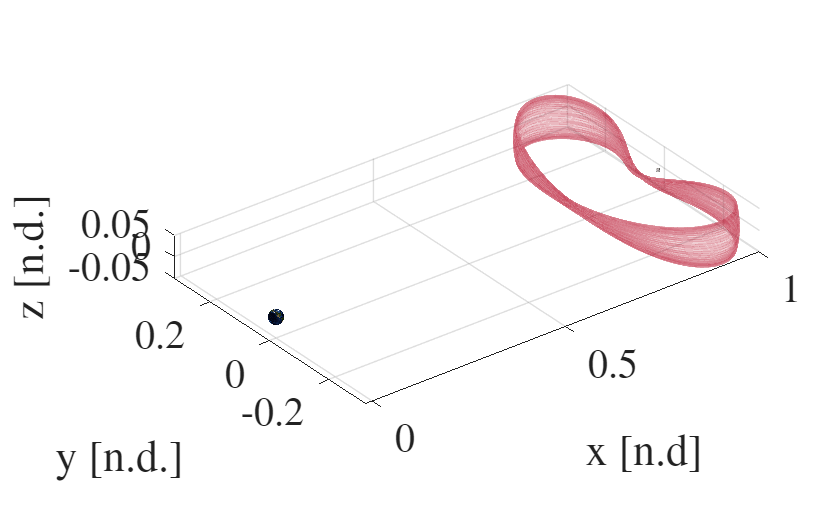

ans =   Surface with properties:

       EdgeColor: 'none'
       LineStyle: '-'
       FaceColor: 'texturemap'
    FaceLighting: 'flat'
       FaceAlpha: 1
           XData: [1001×1001 double]
           YData: [1001×1001 double]
           ZData: [1001×1001 double]
           CData: [2700×5400×3 uint8]

  Show all properties

  Show all accessible properties of Surface


 plot_Earth_nd(1e3,1,1)

[X0,T,rho] = gmos_unpack_z(z_sol, N);
r = X0(1:3,:);
fprintf('range x: [%.3g, %.3g]\n', min(r(1,:)), max(r(1,:)));

range x: [0.759, 0.759]


fprintf('range y: [%.3g, %.3g]\n', min(r(2,:)), max(r(2,:)));

range y: [-7.09e-20, 7.1e-20]


fprintf('range z: [%.3g, %.3g]\n', min(r(3,:)), max(r(3,:)));

range z: [-1.2e-07, 1.2e-07]


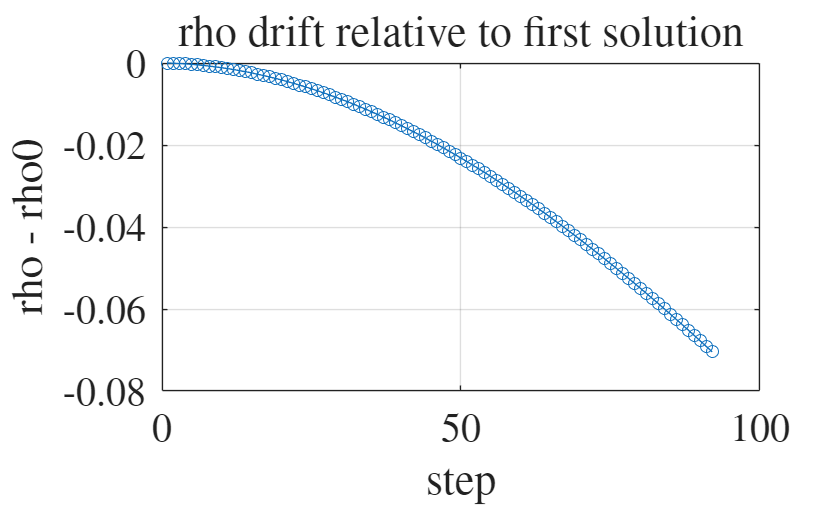

rho0 = fam.rho(1);
figure; plot(fam.rho - rho0, 'o-'); grid on;
xlabel('step'); ylabel('rho - rho0');
title('rho drift relative to first solution');

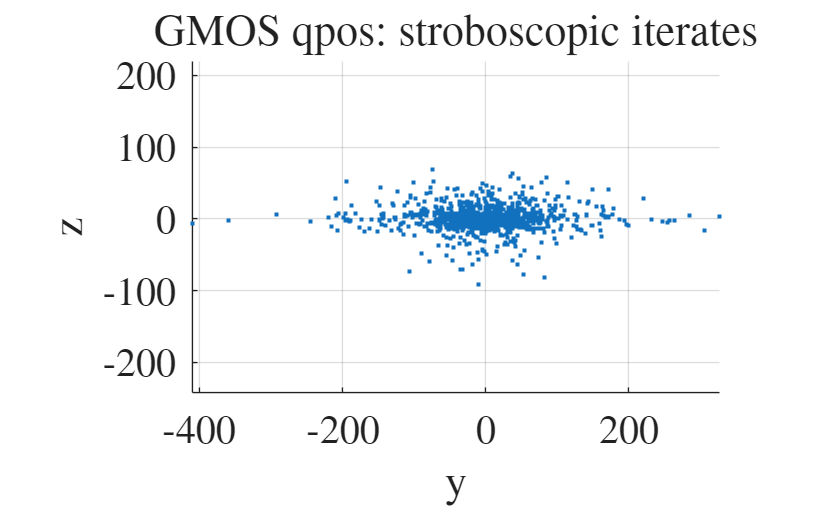

 
ode_opts = odeset('RelTol',1e-12,'AbsTol',1e-12);

step = numel(fam.z);      % last family member (for example)
nIter = 40;               % torus filling density

qpos = gmos_generate_qpos_iterates(fam.z{step}, N, mu_EM_JPL, nIter, ode_opts);
gmos_plot_qpos_points(qpos, 'yz');

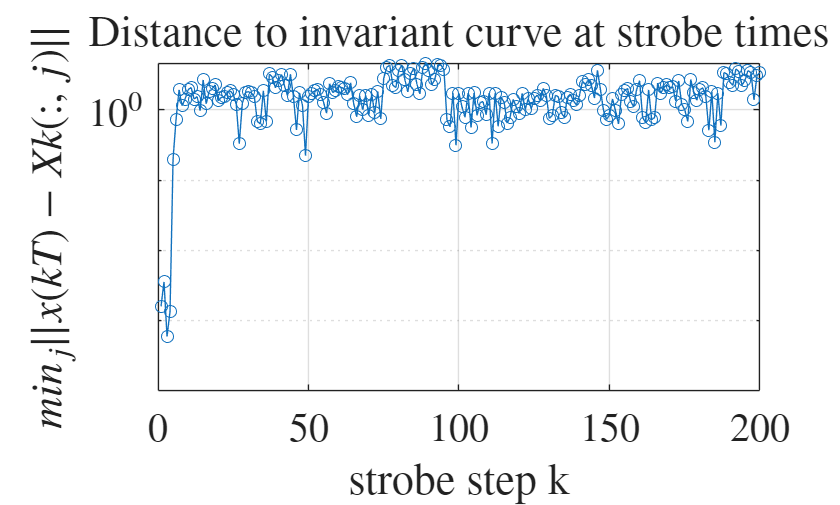

[X0, T, rho] = gmos_unpack_z(z, N);

j0 = 1;
x = X0(:,j0);

nSteps = 200;
errMin = zeros(nSteps,1);

for k = 1:nSteps
    sol = ode113(@(t,y) CR3BP_mu(t,y,mu_EM_JPL), [0,T], x, ode_opts);
    x = sol.y(:,end);

    % Compare to the curve shifted by k*rho
    Xk = gmos_shift_curve_fft(X0, k*rho);

    % Distance to the curve (discrete min)
    diffs = Xk - x;
    d2 = sum(diffs.^2, 1);
    errMin(k) = sqrt(min(d2));
end

figure; semilogy(errMin,'o-'); grid on;
xlabel('strobe step k'); ylabel('$min_j ||x(kT) - Xk(:,j)||$');
title('Distance to invariant curve at strobe times');

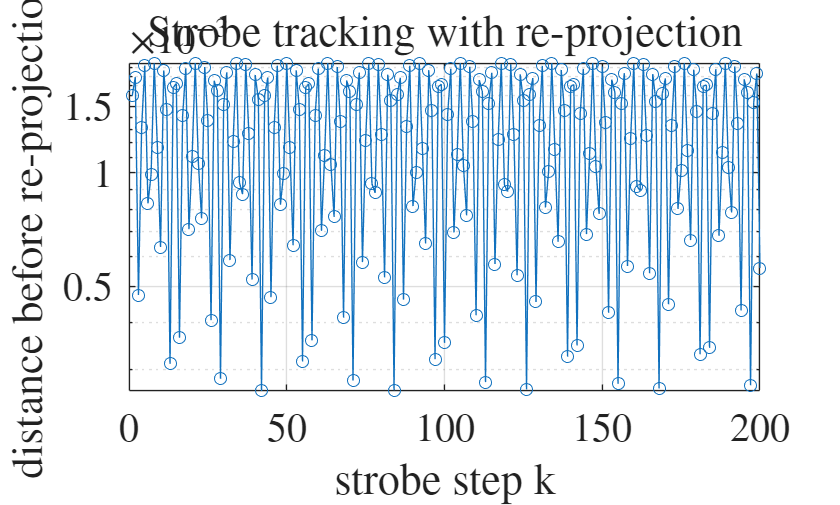

[X0, T, rho] = gmos_unpack_z(z, N);

x = X0(:,1);
nSteps = 200;
err = zeros(nSteps,1);

for k = 1:nSteps
    sol = ode113(@(t,y) CR3BP_mu(t,y,mu_EM_JPL), [0,T], x, ode_opts);
    x = sol.y(:,end);

    Xk = gmos_shift_curve_fft(X0, k*rho);

    diffs = Xk - x;
    d2 = sum(diffs.^2, 1);
    [err(k), jmin] = min(d2);
    err(k) = sqrt(err(k));

    % re-project (shadowing)
    x = Xk(:, jmin);
end

figure; semilogy(err,'o-'); grid on;
xlabel('strobe step k'); ylabel('distance before re-projection');
title('Strobe tracking with re-projection');


beep

[EGMOS, delta] = gmos_accuracy_test_paper(z_sol, N, mu_EM_JPL, ode_opts);
fprintf('Paper accuracy EGMOS = %.3e\n', EGMOS);

Paper accuracy EGMOS = 5.422e-11


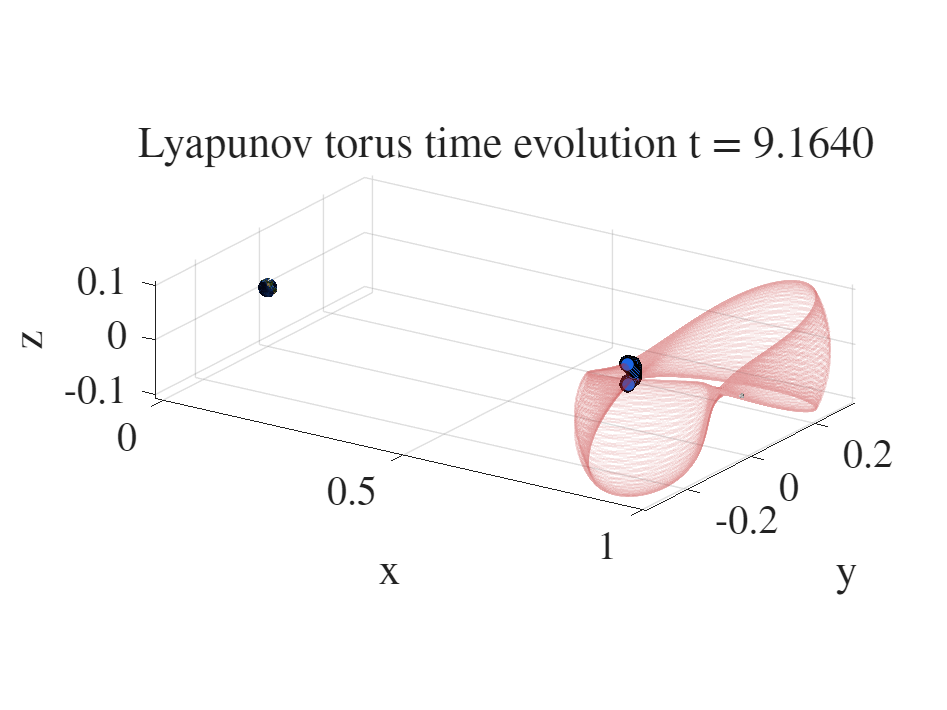

% ------------------------------------------------------------
% Animate one Lyapunov torus with moving particles
% and a constantly rotating camera
% ------------------------------------------------------------
fam_lyap=fam;
% Example: choose one Lyapunov torus solution
z = fam_lyap.z{end};   % replace with your Lyapunov family variable if needed

jList = 1:1:N;
nPeriods = 2;
nSavePerPeriod = 400;

traj = gmos_propagate_qpos_orbits( ...
    z, N, mu_EM_JPL, jList, nPeriods, nSavePerPeriod, ode_opts);

Y = traj.Y;                      % 6 x K x M
[~, K, M] = size(Y);

if isfield(traj, 't')
    tvec = traj.t;
elseif isfield(traj, 'tout')
    tvec = traj.tout;
else
    tvec = 1:K;
end

% Animation settings
frameStride = 3;
fps = 20;
outFile = 'gmos_lyapunov_torus_animation.mp4';

az0 = 35;
el0 = 20;
markerSize = 45;

fig = figure('Color','w','Position',[100 100 1200 900]);
ax = axes(fig);
hold(ax,'on');
grid(ax,'on');
axis(ax,'equal');
view(ax, az0, el0);
xlabel(ax,'x');
ylabel(ax,'y');
zlabel(ax,'z');
title(ax,'Lyapunov torus time evolution');

% Plot faint background torus
for m = 1:M
    r = squeeze(Y(1:3,:,m));
    patch(ax, ...
        'XData', [r(1,:) nan], ...
        'YData', [r(2,:) nan], ...
        'ZData', [r(3,:) nan], ...
        'FaceColor', 'none', ...
        'EdgeColor', [0.75 0.15 0.15], ...
        'EdgeAlpha', 0.08, ...
        'LineWidth', 1.0);
end

% Fix axis limits once
xmin = min(Y(1,:,:), [], 'all'); xmax = max(Y(1,:,:), [], 'all');
ymin = min(Y(2,:,:), [], 'all'); ymax = max(Y(2,:,:), [], 'all');
zmin = min(Y(3,:,:), [], 'all'); zmax = max(Y(3,:,:), [], 'all');

dx = xmax - xmin; dy = ymax - ymin; dz = zmax - zmin;
pad = 0.08 * max([dx dy dz]);

xlim(ax, [xmin-pad, xmax+pad]);
ylim(ax, [ymin-pad, ymax+pad]);
zlim(ax, [zmin-pad, zmax+pad]);

% Earth and Moon
plot_Earth_nd(1e3,60,1);
plot_Moon_nd(1e3,60,1);

% Initial simultaneous ring
x = squeeze(Y(1,1,:));
y = squeeze(Y(2,1,:));
zring = squeeze(Y(3,1,:));

hRing = plot3(ax, [x; x(1)], [y; y(1)], [zring; zring(1)], ...
    '-', 'Color', [0.85 0.1 0.1], 'LineWidth', 1.5);

hPts = scatter3(ax, x, y, zring, markerSize, ...
    'filled', ...
    'MarkerFaceColor', [0.1 0.4 0.9], ...
    'MarkerEdgeColor', 'k');

% Video writer
v = VideoWriter(outFile, 'MPEG-4');
v.FrameRate = fps;
open(v);

frameIdx = 1:frameStride:K;
nFrames = numel(frameIdx);

for ii = 1:nFrames
    k = frameIdx(ii);

    x = squeeze(Y(1,k,:));
    y = squeeze(Y(2,k,:));
    zring = squeeze(Y(3,k,:));

    set(hPts, 'XData', x, 'YData', y, 'ZData', zring);
    set(hRing, 'XData', [x; x(1)], 'YData', [y; y(1)], 'ZData', [zring; zring(1)]);

    % Constant camera rotation
    az = az0 + 360*(ii-1)/nFrames;
    view(ax, az, el0);

    if numel(tvec) == K
        title(ax, sprintf('Lyapunov torus time evolution   t = %.4f', tvec(k)));
    else
        title(ax, sprintf('Lyapunov torus time evolution   frame = %d', k));
    end

    drawnow;
    writeVideo(v, getframe(fig));
end


close(v);
fprintf('Saved animation to %s\n', outFile);

Saved animation to gmos_lyapunov_torus_animation.mp4


DRO Paper Example

clear 
clc


orbit_index=600

po = pick_po_from_JPL('DRO_orbits_JPL_IC_Earth_Moon.csv', orbit_index);  % your DRO file
xPO0 = po.x0(:);
TPO  = po.T;

% Enforce planar subspace
xPO0(3) = 0; xPO0(6) = 0;

ode_opts = odeset('RelTol',1e-12,'AbsTol',1e-12);
sol = ode113(@(t,y) CR3BP_mu(t,y,mu), [0,TPO], xPO0, ode_opts);
fprintf('DRO closure error = %.3e\n', norm(sol.y(:,end)-xPO0));

N = 25;                 % paper style
K = 1e-5;               % small amplitude
Ttarget = TPO;

demo = gmos_demo_invariance_only(mu, xPO0, TPO, N, K, false, 'planar');
init = demo.init;

% Use init as reference (paper)
Xref   = init.X0;
Tref   = init.T0;
rhoref = init.rho0;

z0 = gmos_pack_z(init.X0, init.T0, init.rho0);

optsN = struct('maxIter', 8, 'tolInf', 1e-10, 'verbose', true);
[z_sol, info] = gmos_newton_fixT_analytic(z0, N, mu, Xref, Tref, rhoref, Ttarget, ode_opts, optsN);

[X0, T, rho] = gmos_unpack_z(z_sol, N);

figure; hold on; grid on; axis equal;
plot(X0(1,:), X0(2,:), 'o-');
xlabel('x'); ylabel('y');
title(sprintf('Invariant curve (x-y), N=%d', N));

[EGMOS, delta] = gmos_accuracy_test_paper(z_sol, N, mu_EM_JPL, ode_opts);

figure; semilogy(1:N, delta, 'o-'); grid on;
xlabel('curve index i'); ylabel('delta_i');
title(sprintf('Paper midpoint errors, EGMOS=%.3e', EGMOS));

jList = 1:5:N;
nPeriods = 5;
nSavePerPeriod = 200;

traj = gmos_propagate_qpos_orbits(z_sol, N, mu_EM_JPL, jList, nPeriods, nSavePerPeriod, ode_opts);
gmos_plot_qpos_orbits_3d(traj, struct('mode','index','alpha',0.4,'lineWidth',1.0));

figure; hold on; grid on; axis equal;
for m = 1:numel(jList)
    r = squeeze(traj.Y(1:3,:,m));
    plot(r(1,:), r(2,:), '-');
end
xlabel('x'); ylabel('y');
title('Propagated QPO trajectories (x-y)');

[EGMOS, delta] = gmos_accuracy_test_paper(z_sol, N, mu, ode_opts);
fprintf('Paper accuracy EGMOS = %.3e, max(delta)=%.3e\n', EGMOS, max(delta));

N2 = 51;

demo2 = gmos_demo_invariance_only(mu, xPO0, TPO, N2, K, false, 'planar');
init2 = demo2.init;

Xref2   = init2.X0;
Tref2   = init2.T0;
rhoref2 = init2.rho0;

z02 = gmos_pack_z(init2.X0, init2.T0, init2.rho0);

[z_sol2, ~] = gmos_newton_fixT_analytic(z02, N2, mu, Xref2, Tref2, rhoref2, Ttarget, ode_opts, optsN);

[EGMOS2, ~] = gmos_accuracy_test_paper(z_sol2, N2, mu, ode_opts);

fprintf('EGMOS N=25: %.3e\n', EGMOS);
fprintf('EGMOS N=51: %.3e\n', EGMOS2);

%DRO FAMILY
% 
% 
clear
clc


set(0,'DefaultFigureWindowStyle','normal');

set(groot,'DefaultTextInterpreter','latex');
set(groot,'DefaultAxesTickLabelInterpreter','latex');
set(groot,'DefaultLegendInterpreter','latex');
set(groot,'DefaultAxesFontSize',20);
set(groot,'DefaultTextFontSize',22);

% -------------------------
% Constants
% -------------------------
mu_EM_JPL = 1.215058560962404e-2;

mu=mu_EM_JPL

orbit_index = 400;

po = pick_po_from_JPL('DRO_orbits_JPL_IC_Earth_Moon.csv', orbit_index);
xPO0 = po.x0(:);
TPO  = po.T;


% -------------------------
% Quick trajectory plot (optional)
% -------------------------
[t_eval, Y_eval] = IntegrateCR3BP_ODE89(xPO0, [0, TPO], mu_EM_JPL, 1e3);

figure;
hold on; grid on; axis equal;
plot3(Y_eval(:,1), Y_eval(:,2), Y_eval(:,3));
xlabel('x'); ylabel('y'); zlabel('z');
title('JPL DRO orbit propagation');




% xPO0(3) = 0;
% xPO0(6) = 0;

ode_opts = odeset('RelTol',1e-12,'AbsTol',1e-12);

sol = ode89(@(t,y) CR3BP_mu(t,y,mu), [0, TPO], xPO0, ode_opts);
fprintf('DRO closure error = %.3e\n', norm(sol.y(:,end) - xPO0));

N = 51;
Ttarget = TPO;
mode = 'planar';

K0 = 1e-4;
K1 = 5e-4;

demo0 = gmos_demo_invariance_only(mu, xPO0, TPO, N, K0, false, mode);
demo1 = gmos_demo_invariance_only(mu, xPO0, TPO, N, K1, false, mode);

init0 = demo0.init;
init1 = demo1.init;

Xref   = init0.X0;
Tref   = init0.T0;
rhoref = init0.rho0;

z0 = gmos_pack_z(init0.X0, init0.T0, init0.rho0);
z1 = gmos_pack_z(init1.X0, init1.T0, init1.rho0);

optsN = struct('maxIter',16,'tolInf',1e-10,'verbose',true);

[z0_sol, info0] = gmos_newton_fixT_analytic( ...
    z0, N, mu, Xref, Tref, rhoref, Ttarget, ode_opts, optsN);

[z1_sol, info1] = gmos_newton_fixT_analytic( ...
    z1, N, mu, Xref, Tref, rhoref, Ttarget, ode_opts, optsN);

fprintf('seed 0 final ||F||inf = %.3e\n', info0.normInf(end));
fprintf('seed 1 final ||F||inf = %.3e\n', info1.normInf(end));

ds = 1e-2;
nSteps = 100;

if isfile('fam_fixT_DRO.mat')
    load('fam_fixT_DRO.mat','fam')
else
    fam = gmos_continue_fixT_family( ...
        z0_sol, z1_sol, nSteps, ds, N, mu, Ttarget, ode_opts, optsN);
  %  save('fam_fixT_DRO.mat','fam')
end

beep

idxList = unique(round(linspace(1, numel(fam.z), min(10, numel(fam.z)))));


figure
hold on
grid on
axis equal
for ii = idxList(:).'
    [X0i, ~, ~] = gmos_unpack_z(fam.z{ii}, N);
    scatter3(X0i(1,:), X0i(2,:),X0i(3,:), 'filled')
end
xlabel('x')
ylabel('y')
title('DRO GMOS family: invariant curves')

z = fam.z{end};


jList = 1:1:N;
nPeriods = 1;
nSavePerPeriod = 300;

traj = gmos_propagate_qpos_orbits( ...
    z, N, mu, jList, nPeriods, nSavePerPeriod, ode_opts);

gmos_plot_qpos_orbits_3d( ...
    traj, struct('mode','rgb','rgb',[0.7 0.0 0.1],'alpha',0.1,'lineWidth',1.2),0);
plot_Moon_nd(1e3,1,1);
plot_Earth_nd(1e3,1,1);

[EGMOS_end, delta_end] = gmos_accuracy_test_paper(z, N, mu, ode_opts);
fprintf('Last family member: EGMOS = %.3e, max(delta) = %.3e\n', EGMOS_end, max(delta_end));

EG = nan(numel(fam.z),1);
for k = 1:numel(fam.z)
    [EG(k), ~] = gmos_accuracy_test_paper(fam.z{k}, N, mu, ode_opts);
end


figure
semilogy(1:numel(EG), EG, 'o-')
grid on
xlabel('family index')
ylabel('$E_{GMOS}$')
title('DRO family accuracy (N=51)')

HALO QPOs

clear
clc

% =========================================================
% Minimal GMOS halo script
% =========================================================

% -------------------------
% Constants
% -------------------------

mu_EM_JPL = 1.215058560962404e-2;

mu = mu_EM_JPL;
ode_opts = odeset('RelTol',1e-12,'AbsTol',1e-12);

% -------------------------
% Pick one halo orbit from JPL
% -------------------------
%orbit_index = 896;

orbit_index = 200;
po = pick_po_from_JPL('L1_northern_halo_orbits_JPL_IC_Earth_Moon.csv', orbit_index);

xPO0 = po.x0;
TPO  = po.T;

fprintf('Using halo orbit index %d\n', orbit_index);
fprintf('TPO = %.15f\n', TPO);

% -------------------------
% Plot the periodic orbit itself
% -------------------------
[t_eval, Y_eval] = IntegrateCR3BP_ODE89(xPO0, [0, TPO], mu, 1000);

figure;
hold on; grid on; axis equal;
plot3(Y_eval(:,1), Y_eval(:,2), Y_eval(:,3), 'k', 'LineWidth', 1.2);
plot_Moon_nd(1e3,1,1);
xlabel('x'); ylabel('y'); zlabel('z');
title('Original halo periodic orbit');

% -------------------------
% Periodic orbit closure check
% -------------------------
solPO = ode89(@(t,Y) CR3BP_mu(t,Y,mu), [0, TPO], xPO0, ode_opts);
x_end = solPO.y(:,end);
fprintf('PO closure error = %.3e\n', norm(x_end - xPO0));

% -------------------------
% Monodromy eigenvalues
% -------------------------
M_eigs = monodromy_CR3BP([0, TPO], xPO0, mu);
V = M_eigs(:,1:6);
D = M_eigs(:,7:12);
lam = diag(D);

fprintf('\nMonodromy eigenvalues:\n');
disp(lam)

figure;
th = linspace(0, 2*pi, 400);
plot(cos(th), sin(th), 'k--'); hold on; grid on; axis equal;
plot(real(lam), imag(lam), 'o', 'MarkerSize', 8, 'LineWidth', 1.2);
xlabel('$Re(\lambda)$');
ylabel('$Im(\lambda)$');
title('Monodromy eigenvalues');

% -------------------------
% Choose the relevant center mode and K
% -------------------------
% Start with one mode, then switch if the projection printout suggests otherwise
mode = 'vertical';   % try 'vertical' first, then 'planar' if needed
N    = 51;
K    = 1e-2;         % first try very small, then increase gradually

cen = gmos_center_eigpair_from_monodromy([0, TPO], xPO0, mu, mode);

fprintf('\nChosen mode: %s\n', mode);
fprintf('Selected lambda = %.15f %+ .15fi\n', real(cen.lambda), imag(cen.lambda));
fprintf('rho0 = %.15f\n', cen.rho0);
fprintf('planar projection   = %.3e\n', cen.proj.planar);
fprintf('vertical projection = %.3e\n', cen.proj.vertical);

% -------------------------
% Build the initial invariant-curve guess
% -------------------------
init = gmos_init_curve_from_center_mode(xPO0, TPO, cen, N, K, false);

figure;
scatter3(init.X0(1,:), init.X0(2,:), init.X0(3,:), 18, 'filled');
hold on; grid on; axis equal;
plot3(Y_eval(:,1), Y_eval(:,2), Y_eval(:,3), 'k', 'LineWidth', 1.0);
plot_Moon_nd(1e3,1,1);
xlabel('x'); ylabel('y'); zlabel('z');
title('Initial GMOS invariant-curve guess');

% -------------------------
% Initial invariance diagnostic
% -------------------------
demo = gmos_demo_invariance_only(mu, xPO0, TPO, N, K, false, mode);
fprintf('\nInitial invariance diagnostic:\n');
fprintf('||Finv||2   = %.3e\n', demo.norm2);
fprintf('||Finv||inf = %.3e\n', demo.normInf);

% -------------------------
% Newton solve with fixed T = TPO
% -------------------------
Xref   = init.X0;
Tref   = init.T0;
rhoref = init.rho0;
z0     = gmos_pack_z(init.X0, init.T0, init.rho0);

optsN = struct();
optsN.maxIter = 12;
optsN.tolInf  = 1e-10;
optsN.verbose = true;

tic

[z_sol, info] = gmos_newton_fixT_analytic( ...
    z0, N, mu, Xref, Tref, rhoref, TPO, ode_opts, optsN);

toc

[X0_sol, T_sol, rho_sol] = gmos_unpack_z(z_sol, N);

fprintf('\nSolved torus:\n');
fprintf('T   = %.15f\n', T_sol);
fprintf('rho = %.15f\n', rho_sol);
fprintf('final ||F||inf = %.3e\n', info.normInf(end));

% -------------------------
% Plot the solved invariant curve
% -------------------------
figure;
scatter3(X0_sol(1,:), X0_sol(2,:), X0_sol(3,:), 24, 'filled');
hold on; grid on; axis equal;
plot3(Y_eval(:,1), Y_eval(:,2), Y_eval(:,3), 'k', 'LineWidth', 1.0);
plot_Moon_nd(1e3,1,1);
xlabel('x'); ylabel('y'); zlabel('z');
title('Solved invariant curve around halo orbit');


% -------------------------
% Propagate representative trajectories on the torus
% -------------------------
jList = 1:1:N;
nPeriods = 3;
nSavePerPeriod = 1000;

traj = gmos_propagate_qpos_orbits( ...
    z_sol, N, mu, jList, nPeriods, nSavePerPeriod, ode_opts);

gmos_plot_qpos_orbits_3d(traj, struct( ...
    'mode','index', ...
    'alpha',1, ...
    'lineWidth',1.0));

title('Quasi-periodic trajectories from solved halo torus');

[X0, ~, ~] = gmos_unpack_z(z_sol, N);

jList = 1:3:N;
traj = gmos_propagate_qpos_orbits(z_sol, N, mu_EM_JPL, jList, 2.1, 300, ode_opts);



gmos_plot_qpos_orbits_3d(traj, struct('mode','rgb','rgb',[0.7 0.0 0.1],'alpha',0.01,'lineWidth',1), 0.65*TPO)
 
plot3(X0(1,:), X0(2,:), X0(3,:), 'ro', 'MarkerSize', 4, 'MarkerFaceColor', 'r')
xlabel('x')
ylabel('y')
zlabel('z')
title('Single torus and its invariant curve')


% -------------------------
% Stroboscopic point diagnostic
% -------------------------
nIter = 4;
qpos = gmos_generate_qpos_iterates(z_sol, N, mu, nIter, ode_opts);

figure;
gmos_plot_qpos_points(qpos, 'xy');
title('Stroboscopic invariant points on the torus');

% -------------------------
% Optional paper-style accuracy metric, if available
% -------------------------
if exist('gmos_accuracy_test_paper', 'file') == 2
    [EGMOS, delta] = gmos_accuracy_test_paper(z_sol, N, mu, ode_opts);
    fprintf('EGMOS = %.3e\n', EGMOS);
end

% -------------------------------------------------
% HALO TORUS FAMILY
% Assumes xPO0, TPO, mu_EM_JPL already exist
% -------------------------------------------------

ode_opts = odeset('RelTol',1e-12,'AbsTol',1e-12);
Ttarget  = TPO;
mode     = 'vertical';
N        = 51;

% Two nearby seed amplitudes
K0 = 8e-3;
K1 = 1e-2;

demo0 = gmos_demo_invariance_only(mu_EM_JPL, xPO0, TPO, N, K0, false, mode);
demo1 = gmos_demo_invariance_only(mu_EM_JPL, xPO0, TPO, N, K1, false, mode);

init0 = demo0.init;
init1 = demo1.init;

% Use first seed as reference for the two initial Newton solves
Xref   = init0.X0;
Tref   = init0.T0;
rhoref = init0.rho0;

z0 = gmos_pack_z(init0.X0, init0.T0, init0.rho0);
z1 = gmos_pack_z(init1.X0, init1.T0, init1.rho0);

optsN = struct('maxIter',12,'tolInf',1e-10,'verbose',true);

[z0_sol, info0] = gmos_newton_fixT_analytic( ...
    z0, N, mu_EM_JPL, Xref, Tref, rhoref, Ttarget, ode_opts, optsN);

[z1_sol, info1] = gmos_newton_fixT_analytic( ...
    z1, N, mu_EM_JPL, Xref, Tref, rhoref, Ttarget, ode_opts, optsN);

fprintf('seed 0 final ||F||inf = %.3e\n', info0.normInf(end));
fprintf('seed 1 final ||F||inf = %.3e\n', info1.normInf(end));

% Continue the family
ds     = 2e-3;
nSteps = 100;

if isfile('fam_fixT_halo.mat')
    load('fam_fixT_halo.mat','fam')
else
    fam = gmos_continue_fixT_family( ...
        z0_sol, z1_sol, nSteps, ds, N, mu_EM_JPL, Ttarget, ode_opts, optsN);
    save('fam_fixT_halo.mat','fam')
end

% Plot invariant curves from several family members
idxList = unique(round(linspace(1, numel(fam.z), min(10, numel(fam.z)))));

figure
hold on
grid on
axis equal
for ii = idxList(:).'
    [X0, ~, ~] = gmos_unpack_z(fam.z{ii}, N);
    scatter3(X0(1,:), X0(2,:), X0(3,:), 'filled')
end
xlabel('x')
ylabel('y')
zlabel('z')
title('Halo GMOS family: invariant curves')


% Plot one torus from the last family member
z = fam.z{100};

%z = fam.z{10};

jList = 1:1:N;
nPeriods = 2;
nSavePerPeriod = 400;

traj = gmos_propagate_qpos_orbits( ...
    z, N, mu_EM_JPL, jList, nPeriods, nSavePerPeriod, ode_opts);

gmos_plot_qpos_orbits_3d( ...
    traj, struct('mode','rgb','rgb',[0.7 0.0 0.1],'alpha',0.08,'lineWidth',1.2),1);

plot_Moon_nd(1e3,60,1);

% ------------------------------------------------------------
% Animate one torus with moving particles and rotating camera
% ------------------------------------------------------------

Y = traj.Y;                      % 6 x K x M
[~, K, M] = size(Y);

if isfield(traj, 't')
    tvec = traj.t;
elseif isfield(traj, 'tout')
    tvec = traj.tout;
else
    tvec = 1:K;
end

% Animation settings
frameStride = 3;                 % use 1 for smoother, 2-4 for lighter files
fps = 20;
outFile = 'gmos_torus_animation.mp4';

az0 = 35;                        % initial azimuth
el0 = 22;                        % fixed elevation
markerSize = 40;

fig = figure('Color','w','Position',[100 100 1200 900]);
ax = axes(fig);
hold(ax,'on');
grid(ax,'on');
axis(ax,'equal');
view(ax, az0, el0);
xlabel(ax,'x');
ylabel(ax,'y');
zlabel(ax,'z');
title(ax,'GMOS torus time evolution');

% Faint background torus trajectories
for m = 1:M
    r = squeeze(Y(1:3,:,m));
    patch(ax, ...
        'XData', [r(1,:) nan], ...
        'YData', [r(2,:) nan], ...
        'ZData', [r(3,:) nan], ...
        'FaceColor', 'none', ...
        'EdgeColor', [0.7 0.0 0.1], ...
        'EdgeAlpha', 0.08, ...
        'LineWidth', 1.0);
end

% Moon
plot_Moon_nd(1e3,60,1);

% Initial simultaneous ring
x = squeeze(Y(1,1,:));
y = squeeze(Y(2,1,:));
z = squeeze(Y(3,1,:));

hRing = plot3(ax, [x; x(1)], [y; y(1)], [z; z(1)], ...
    '-', 'Color', [0.85 0.1 0.1], 'LineWidth', 1.5);

hPts = scatter3(ax, x, y, z, markerSize, ...
    'filled', ...
    'MarkerFaceColor', [0.1 0.4 0.9], ...
    'MarkerEdgeColor', 'k');

% Video writer
v = VideoWriter(outFile, 'MPEG-4');
v.FrameRate = fps;
open(v);

frameIdx = 1:frameStride:K;
nFrames = numel(frameIdx);

for ii = 1:nFrames
    k = frameIdx(ii);

    x = squeeze(Y(1,k,:));
    y = squeeze(Y(2,k,:));
    z = squeeze(Y(3,k,:));

    set(hPts, 'XData', x, 'YData', y, 'ZData', z);
    set(hRing, 'XData', [x; x(1)], 'YData', [y; y(1)], 'ZData', [z; z(1)]);

    % Constant camera rotation
    az = az0 + 360*(ii-1)/nFrames;
    view(ax, az, el0);

    if numel(tvec) == K
        title(ax, sprintf('GMOS torus time evolution   t = %.4f', tvec(k)));
    else
        title(ax, sprintf('GMOS torus time evolution   frame = %d', k));
    end

    drawnow;
    writeVideo(v, getframe(fig));
end

close(v);
fprintf('Saved animation to %s\n', outFile);